# Practica 1 - Robot PUMA

***NOTA:*** Se han eliminado los acentos y algunos signos en los textos debido a a que la impresion no reconocia los simbolos.

***NOTA:*** Como para cualquier comando de MATLAB se ha utilizado **help **para entender el funcionamiento de los comandos dados en el enunciado de la practica para su desarrollo.

## 1. Carga del robot

Tras iniciar Matlab y cargar EduBot ejecutamos:

puma560

Se ha creado la variable p560, que contiene los datos del modelo del PUMA 560. Estos incluyen los parametos de la tabla D-H y 3 vectores de dimension 6 asociados a diferentes configuraciones aticulares.

- **qr: **posicion de reposo. El brazo del robot se encuentra estirado en vertical.

- **qz: **posicion de cero. Cada articulacion se encuentra en su origen.

- **qstrech: **posicion encogida. El brazo del robot se encuentra estirado en horizontal, con la primera articulacion a 90 grados.

Usando **plot **se pueden visualizar diferentes configuraciones del robot.

Al utilizar este "livescript" a la derecha se mostraran los resultados de ejecucion de cada codigo. Para los plots, sera necesario abrir en una nueva ventana (si seleccionas arriba a la derecha al pinchar en la imagen) la opcion se "sacar la imagen". A partir de ahi, se puede manipular la imagen 3D para posicionar los ejes de forma que se aprecie mejor las posiciones de las articulaciones y elementos del robot.

***NOTA:*** Las figuras se solapan, para poder visualizarlas descomentar la que se quiera visualizar o comentar la que este descomentada. Ademas de esta forma no aparecen las lineas de codigo amarillo (warnings) en la impresion.


% plot(p560,qr)

% plot(p560,qz)

% plot(p560,qstretch)

A continuacion se muestran las imagenes obtenidas al ejecutar cada plot respectivamente.

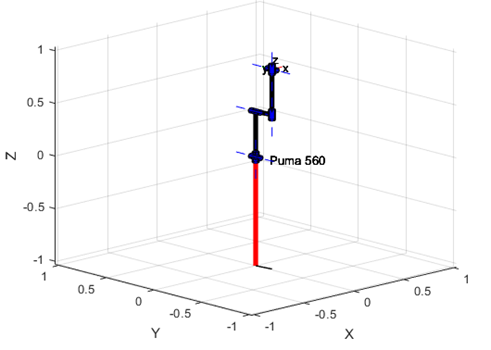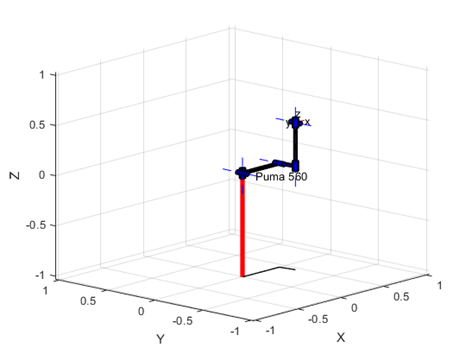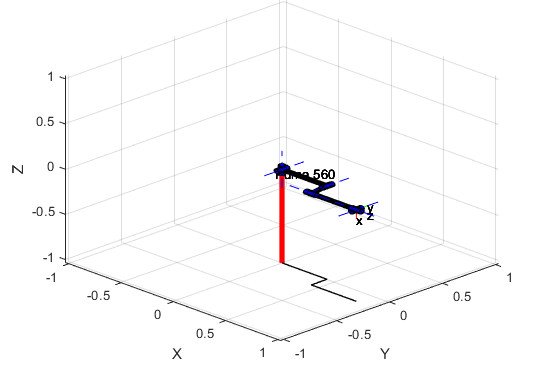

## 2. Problema cinematico directo del robot

Mediante **fkine **se obtiene la matriz de transformacion $T_1$ asociada a la configuracion articular $q_1$  

q1 = [0 0 -pi/4 pi/4 pi/10 0]; % (rad)
fkine(p560,q1);        

Se pide la visualizacion del robot en dicha posicion y extraer de la matriz de transformacion  $T_1$ la posicion TCP (punto de la herramienta) en el espacio cartesiano y la orientacion del sistema de referencia movil usando la notacion Roll/Pitch/Yaw.

T1 = fkine(p560,q1)

T1 =     0.6940   -0.5000    0.5180    0.7515
    0.6725    0.7071   -0.2185   -0.1500
   -0.2570    0.5000    0.8270    0.2910
         0         0         0    1.0000


% plot(p560,q1)

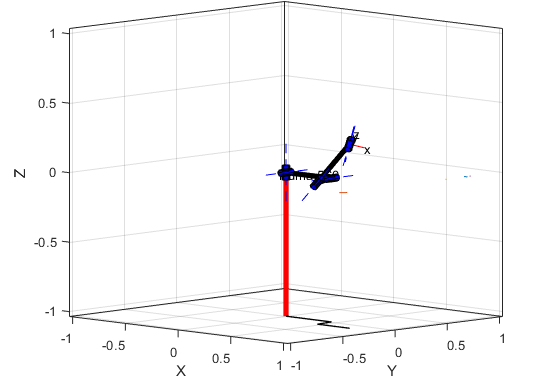

**Posicion TCP**

posicionT1 = T1(1:3,4)

posicionT1 =     0.7515
   -0.1500
    0.2910


**Orientacion del sistema movil usando la notacion Roll/Pitch/Yaw (rad)**

R = atan (T1(1,3)/T1(2,3))

R = -1.1716

P = atan (sqrt((T1(1,3))^2+(T1(2,3))^2)/T1(3,3))

P = 0.5970

Y = atan (T1(3,1)/T1(3,2))

Y = -0.4748

## 3. Problema cinematico inverso del robot usando el procedimiento generico recursivo.

Mediante el comando **ikine, **determinar la condiguracion articular $q_2$ asociada a al matriz de transformacion $T_2$

T2 = [ 0   0   0   0.8636;
       0   1   0  -0.1501;
      -1   0   0  -0.0203;
       0   0   0   1]

T2 =          0         0         0    0.8636
         0    1.0000         0   -0.1501
   -1.0000         0         0   -0.0203
         0         0         0    1.0000


** a) **   Dado que **ikine **utiliza un metodo numerico general para su resolucion, es necesario utilizar una semilla o configuracion $q_0$ de partida para el calculo ue este suficientemente cerca del punto final.

Con el fin de ver el efecto de la semilla inicial, se calculara la configuracion articular que permite que el robot presetne una localizacion definida por $T_2$, en vase a dos posible semillas de partida

- La semilla $q_{0a} =\left\lbrack 0\;\;0\;\;0\;\;0\;\;0\;\;0\right\rbrack$ (rad), que es la que **ikine **usa por defecto si se omite la semilla en el comando

   q0a = [0 0 0 0 0 0]

q0a =      0     0     0     0     0     0


   
   q2a = ikine(p560,T2)

q2a =    -0.0001   -0.0466   -1.4777    0.0012   -0.0465   -0.0012


   % que es equivalente a 
   q2a = ikine(p560,T2,q0a)

q2a =    -0.0001   -0.0466   -1.4777    0.0012   -0.0465   -0.0012


- La semilla $q_{0b} =\left\lbrack 0\;\;0\;\;0\;-\pi \;\;0\;\;\pi \right\rbrack$ (rad)

   q0b = [0 0 0 -pi 0 pi]

q0b =          0         0         0   -3.1416         0    3.1416


   q2b = ikine(p560,T2,q0b)

q2b =    -0.0001   -0.0466   -1.4777   -3.1403    0.0465    3.1403


**b)    **Represente las configuraciones ${\mathit{\mathbf{q}}}_{2\mathit{\mathbf{a}}}$ y $\;{\mathit{\mathbf{q}}}_{2\mathit{\mathbf{b}}}$ mediante el comando **plot. **¿Que observa?

%    plot(p560,q2a)

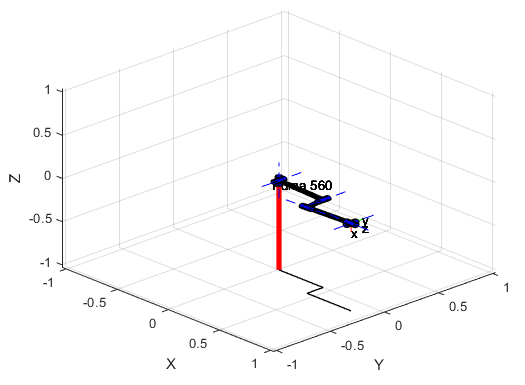

% plot(p560,q2b)

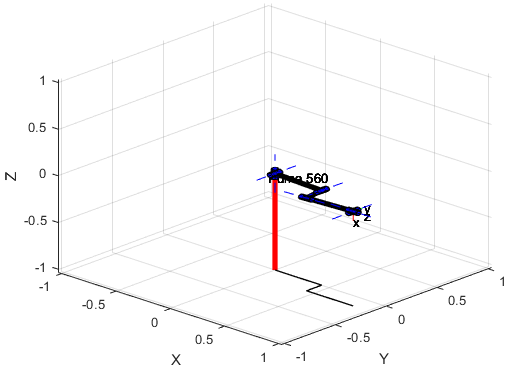

**Observacion**

Se puede observar que presentan la misma configuracion. Esto se debe a que 0 rad equivale a -3,14 rad, y para la diferencia de signo entre la coordenada articular 5 es la misma posicion pero en sentido contrario.

**c) **   Use **fkine **para determinar la localizacion del robt asociadas a las configuraciones ${\mathit{\mathbf{q}}}_{2\mathit{\mathbf{a}}}$ y $\;{\mathit{\mathbf{q}}}_{2\mathit{\mathbf{b}}}$, definidas por las matrices de transformacion $T_{2\mathit{\mathbf{a}}}$ y $\;T_{2\mathit{\mathbf{b}}}$. ¿Que conclusion extrae?

T2a = fkine(p560,q2a)

T2a =     0.0000   -0.0000    1.0000    0.8636
         0    1.0000    0.0000   -0.1501
   -1.0000    0.0000    0.0000   -0.0203
         0         0         0    1.0000


T2b = fkine(p560,q2b)

T2b =     0.0000   -0.0000    1.0000    0.8636
    0.0000    1.0000    0.0000   -0.1501
   -1.0000    0.0000    0.0000   -0.0203
         0         0         0    1.0000


**Conclusion**

Al final con el problema cinematico inverso pueden haber mas de una solucion. Se ha partido de dos semillas distintas, peroal final la posicion de la punta es la misma.

## 4. Problema cinematico inverso del robot usando una solucion analitica

Determinar, usando el comando **ikine560, **la configuracion articular ${\mathit{\mathbf{q}}}_2$ asociada a la matriz de transformacion $T_3$

   T3 = [ 0   0   1   0.7580;
          0   1   0  -0.1500;
         -1   0   0  -0.0176;
          0   0   0   1]

T3 =          0         0    1.0000    0.7580
         0    1.0000         0   -0.1500
   -1.0000         0         0   -0.0176
         0         0         0    1.0000


Este comando, **ikine560, **permite obtener la solucion analitica específica del Puma 560. Mediante el se especifica la configuracion particular deseada. 

Se pide cacular las soluciones para alcanzar la localizacion marcada por una matriz de transformacion $T_3$ con las siguientes configuraciones especificas:

- ${\mathit{\mathbf{q}}}_{3\mathit{\mathbf{a}}}$ : Hombro izquierda, codo arriba, flip.

- ${\mathit{\mathbf{q}}}_{3b}$ : Hombro izquierda, codo abajo, flip.

- ${\mathit{\mathbf{q}}}_{3c}$ : Hombro derecha, codo abajo, noflip.

q3a = ikine560(p560,T3,'luf')

q3a =     2.7508   -3.6189   -0.5233    2.4896    0.6788    0.5361


q3b = ikine560(p560,T3,'ldf')

q3b =     2.7508   -2.6178   -2.5243    0.7798    0.5725    2.4482


q3c = ikine560(p560,T3,'rdn')

q3c =     0.0001   -0.5238   -0.5233   -0.0001   -0.5237    0.0001


Mediante el comando **plot **se visualizaran las tres configuraciones. Posteriormente se analizaran las diferencias.

% plot(p560,q3a)

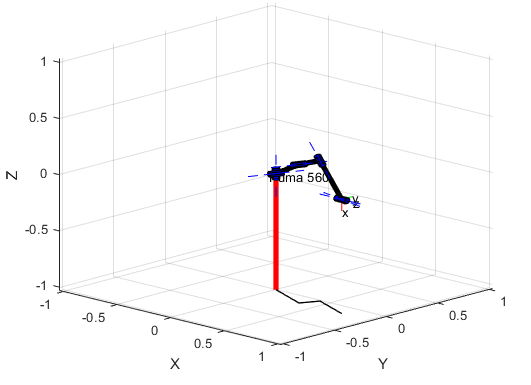

% plot(p560,q3b)

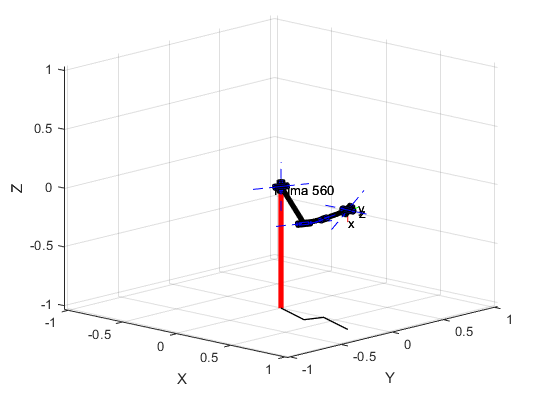

% plot(p560,q3c)

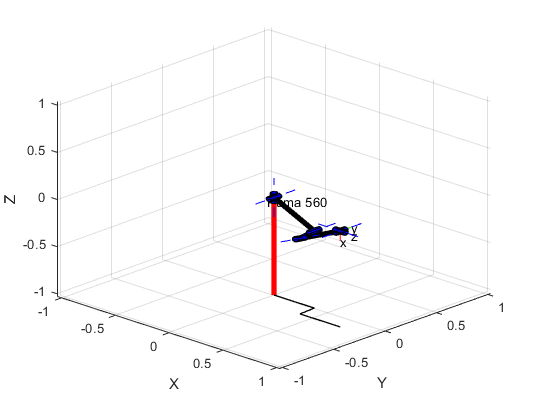

**Analisis**

Se observa como la configuracion espeficiada en el codigo modifica la configuracion de las articulaciones, pero que la posicion final de la punta es la misma para los tres casos.

Mediante el comando **help ikine560 **se puede observar en detalle las disntas condifuraciones posibles. 

help ikine560

 ikine560 Inverse kinematics for Puma 560 
 
 	Q = ikine560(ROBOT, T, CONFIG)
 
  Solve the inverse kinematics of the Puma-like (spherical wristed) robot 
  ROBOT whose end-effector pose is given by T.
 
  The optional third argument specifies the configuration of the arm in
  the form of a string containing one or more of the configuration codes:
 	'l' or 'r'	lefty/righty
 	'u' or 'd'	elbow
 	'n' or 'f'	wrist flip or noflip.
 
  The default configuration is 'lun'.
 
  REFERENCE:
 
  Inverse kinematics for a PUMA 560 based on the equations by Paul and Zhang
  From The International Journal of Robotics Research
  Vol. 5, No. 2, Summer 1986, p. 32-44
 
 
  AUTHOR:
  Robert Biro		gt2231a@prism.gatech.edu
  with Gary Von McMurray
 
  GTRI/ATRP/IIMB
  Georgia Institute of Technology
  2/13/95



## 5. Coste computacional del modilo cinematico

Se procede a comparar el coste computacional del calculo del modelo cinematico inverso usando el metodo numerico general y analitico. Para ello se utilizara la matriz de transformacion $T_3$.

fprintf("Metodo numerico general")

Metodo numerico general

tic
ikine(p560,T3)

ans =     0.0001   -0.5238   -0.5233   -0.0001   -0.5237    0.0001


toc

Elapsed time is 0.030633 seconds.


fprintf("Metodo numerico analitico")

Metodo numerico analitico

tic
ikine560(p560,T3,'lun')

ans =     2.7508   -3.6189   -0.5233   -0.6520   -0.6788   -2.6055


toc

Elapsed time is 0.013803 seconds.


**Observarciones**

Es mas rapida la solucion analitica. Esto se debe a que el programa tiene que realizar menos calculos, posiblemente porque es una funcion especifica para este robot.